Cálculo de $\pi$

N = 5000;
x = rand(1,N)

x =     0.6641    0.5005    0.4881    0.4486    0.9173    0.1561    0.5618    0.4840    0.7899    0.9549    0.0380    0.9789    0.7888    0.9839    0.5633    0.2595    0.7548    0.1110    0.3507    0.9017    0.4976    0.4217    0.6693    0.1868    0.6337    0.4063    0.5572    0.2153    0.4902    0.6897    0.8758    0.5179    0.5418    0.2272    0.9652    0.9064    0.9448    0.1710    0.9459    0.6708    0.4497    0.2566    0.2309    0.1633    0.5279    0.8148    0.7714    0.2642    0.3626    0.3351


y = rand(1,N)

y =     0.1840    0.2838    0.5816    0.5354    0.5111    0.9392    0.4892    0.2426    0.3570    0.0950    0.9450    0.7534    0.2275    0.6483    0.4317    0.3141    0.7477    0.2197    0.7810    0.6055    0.4388    0.4536    0.5460    0.7904    0.5438    0.9560    0.3133    0.3462    0.9468    0.7447    0.3093    0.5611    0.2804    0.5436    0.7021    0.5918    0.4324    0.8901    0.6629    0.8793    0.5046    0.5006    0.5604    0.4538    0.2635    0.5981    0.9350    0.6399    0.4011    0.9373


% scatter(x,y);
r2 =x.^2  + y.^2 %.Operación elemento x elemento

r2 =     0.4749    0.3310    0.5766    0.4879    1.1026    0.9065    0.5549    0.2931    0.7514    0.9208    0.8945    1.5259    0.6739    1.3883    0.5037    0.1660    1.1286    0.0606    0.7330    1.1797    0.4401    0.3836    0.7461    0.6597    0.6973    1.0791    0.4086    0.1662    1.1367    1.0302    0.8626    0.5830    0.3722    0.3471    1.4245    1.1717    1.0796    0.8215    1.3342    1.2231    0.4568    0.3164    0.3673    0.2326    0.3482    1.0217    1.4693    0.4793    0.2924    0.9907


inside = r2<=1

inside = 1×5000 logical array
   1   1   1   1   0   1   1   1   1   1   1   0   1   0   1   1   0   1   1   0   1   1   1   1   1   0   1   1   0   0   1   1   1   1   0   0   0   1   0   0   1   1   1   1   1   0   0   1   1   1


outside=r2>1

outside = 1×5000 logical array
   0   0   0   0   1   0   0   0   0   0   0   1   0   1   0   0   1   0   0   1   0   0   0   0   0   1   0   0   1   1   0   0   0   0   1   1   1   0   1   1   0   0   0   0   0   1   1   0   0   0


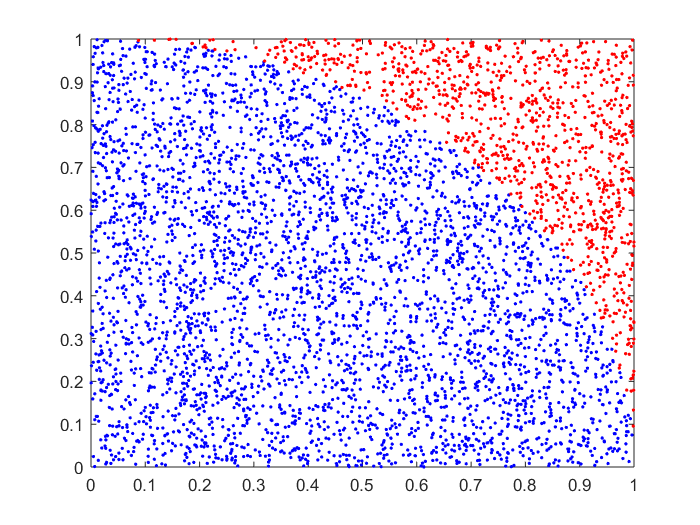

plot(x(inside),y(inside),'b.')
hold on;
plot(x(outside),y(outside), 'r.')

sum(inside)

ans = 3913

sum(outside)

ans = 1087

piCuartos = sum(inside)/N

piCuartos = 0.7826

piAprox= 4*piCuartos

piAprox = 3.1304

y = sqrt(1-x.^2);
promedio = mean(y)

promedio = 0.7843

piAprox= 4*promedio

piAprox = 3.1373

k=10;
pi4=1;
for i = 1:k
    pi4 = pi4 + (-1)^(i)*(1/(2*i+1))
end

pi4 = 0.6667

pi4 = 0.8667

pi4 = 0.7238

pi4 = 0.8349

pi4 = 0.7440

pi4 = 0.8209

pi4 = 0.7543

pi4 = 0.8131

pi4 = 0.7605

pi4 = 0.8081

%Intervalo de confianza al 95% 
x= reshape(r2,[],1)

x =     0.4749
    0.3310
    0.5766
    0.4879
    1.1026
    0.9065
    0.5549
    0.2931
    0.7514
    0.9208


pd = fitdist(x,'Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0.668959   [0.657359, 0.680559]
    sigma = 0.418405   [0.410362, 0.426771]


ci = paramci(pd)

ci =     0.6574    0.4104
    0.6806    0.4268
